# Hidraulico - taller1 corte2

Asignacion de Polos

clear all
clc
syms s

%%Matrices
A=[-4/3 4/3;
    5/3 -15/4]

A =    -1.3333    1.3333
    1.6667   -3.7500


B=[2; 0]

B =      2
     0


C=[0 1]

C =      0     1


D = 0

D = 0

[num,den] = ss2tf(A,B,C,D) 

num =          0         0    3.3333


den =     1.0000    5.0833    2.7778


TF=tf(num,den)

TF =
 
          3.333
  ---------------------
  s^2 + 5.083 s + 2.778
 
Continuous-time transfer function.
Model Properties


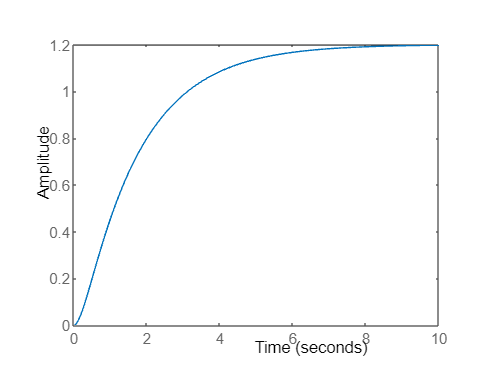

step(TF)

Ts =10; %% Valor propuesto // Santiago le dio 0.48
Tm = Ts/10

Tm = 1

Gd = c2d(TF,Tm,'zoh')

Gd =
 
     0.454 z + 0.09578
  ------------------------
  z^2 - 0.548 z + 0.006199
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties


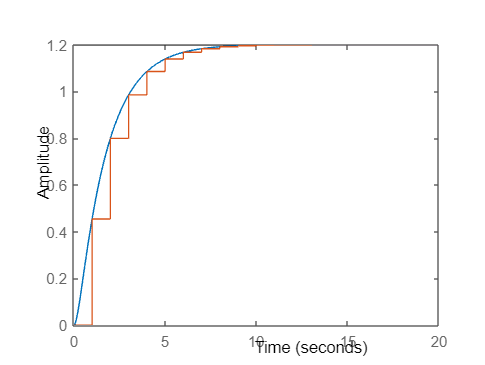

step(TF,Gd)

%%Ts =10; %% Valor propuesto // Santiago le dio 0.48
Tm = 5

Tm = 5

Gd = c2d(TF,Tm,'Tustin')

Gd =
 
  0.6705 z^2 + 1.341 z + 0.6705
  -----------------------------
     z^2 + 1.053 z + 0.1819
 
Sample time: 5 seconds
Discrete-time transfer function.
Model Properties


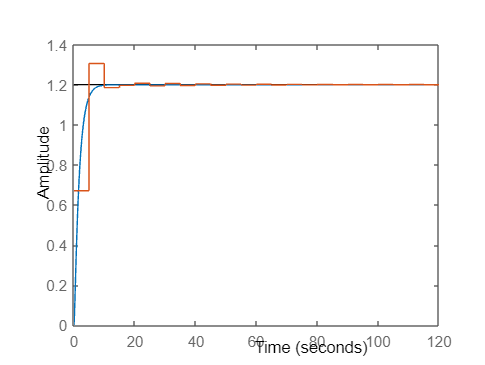

step(TF,Gd)

syms s k1 k2 ki
k=[k1 k2]

$$k = \left(\begin{array}{cc} k_{1} & k_{2} \end{array}\right)$$

sI = s*eye(3)

$$sI = \left(\begin{array}{ccc} s & 0 & 0\\ 0 & s & 0\\ 0 & 0 & s \end{array}\right)$$

Bk= B*[k1 k2]

$$Bk = \left(\begin{array}{cc} 2\,k_{1} & 2\,k_{2}\\ 0 & 0 \end{array}\right)$$

A_Bk = A-Bk

$$A\_Bk = \left(\begin{array}{cc} -2\,k_{1}-\frac{4}{3} & \frac{4}{3}-2\,k_{2}\\ \frac{5}{3} & -\frac{15}{4} \end{array}\right)$$

B_ki= B*[ki]

$$B\_ki = \left(\begin{array}{c} 2\,\mathrm{ki}\\ 0 \end{array}\right)$$


A_asq=[A-Bk B_ki;
    -C 0]

$$A\_asq = \left(\begin{array}{ccc} -2\,k_{1}-\frac{4}{3} & \frac{4}{3}-2\,k_{2} & 2\,\mathrm{ki}\\ \frac{5}{3} & -\frac{15}{4} & 0\\ 0 & -1 & 0 \end{array}\right)$$


sI_A_Bk = sI-A_asq

$$sI\_A\_Bk = \left(\begin{array}{ccc} 2\,k_{1}+s+\frac{4}{3} & 2\,k_{2}-\frac{4}{3} & -2\,\mathrm{ki}\\ -\frac{5}{3} & s+\frac{15}{4} & 0\\ 0 & 1 & s \end{array}\right)$$

PC_0 = det(sI_A_Bk)

$$PC\_0 = \frac{10\,\mathrm{ki}}{3}+\frac{25\,s}{9}+\frac{15\,k_{1}\,s}{2}+\frac{10\,k_{2}\,s}{3}+2\,k_{1}\,s^{2}+\frac{61\,s^{2}}{12}+s^{3}$$

PC=vpa(fliplr(coeffs(PC_0,s)),3)

$$PC = \left(\begin{array}{cccc} 1.0 & 2.0\,k_{1}+5.08 & 7.5\,k_{1}+3.33\,k_{2}+2.78 & 3.33\,\mathrm{ki} \end{array}\right)$$

zeta = 0.8

zeta = 0.8000

ts = 8

ts = 8

wn = 4/(ts*zeta)

wn = 0.6250

betha = 10

betha = 10

PD_0 = ((s^2)+2*zeta*wn*s+wn^2)*(s+betha*zeta*wn)

$$PD\_0 = \left(s+5\right)\,\left(s^{2}+s+\frac{25}{64}\right)$$

PD=vpa(fliplr(coeffs(PD_0,s)),3)

$$PD = \left(\begin{array}{cccc} 1.0 & 6.0 & 5.39 & 1.95 \end{array}\right)$$

f0=vpa(PC(1)==PD(1),3)

$$f0 = 1.0=1.0$$

f1=vpa(PC(2)==PD(2),3)

$$f1 = 2.0\,k_{1}+5.08=6.0$$

f2=vpa(PC(3)==PD(3),3)

$$f2 = 7.5\,k_{1}+3.33\,k_{2}+2.78=5.39$$

f3=vpa(PC(4)==PD(4),3)

$$f3 = 3.33\,\mathrm{ki}=1.95$$

solucion=solve(f1,f2,f3)

solucion = struct with fields:
    k1: 0.45833333331393077969551086425781
    k2: -0.24739583328335659947062002378207
    ki: 0.58593750000341060513166833322688


k1 = double(round(solucion.k1,3))

k1 = 0.4580

k2 = double(round(solucion.k2,3))

k2 = -0.2470

ki = double(round(solucion.ki,3))

ki = 0.5860

Matriz Transformacion con accion integral

disp('Matriz de Transformacion')

Matriz de Transformacion


A_t=[-4/3 4/3 0;
    5/3 -15/4 0;
    0 1 0]

A_t =    -1.3333    1.3333         0
    1.6667   -3.7500         0
         0    1.0000         0


B_t=[2; 0; 0]

B_t =      2
     0
     0


C_t=[0 1 0]

C_t =      0     1     0


D = 0

D = 0

sI_t = s*eye(3)

$$sI\_t = \left(\begin{array}{ccc} s & 0 & 0\\ 0 & s & 0\\ 0 & 0 & s \end{array}\right)$$

sI_t_At = sI_t-A_t

$$sI\_t\_At = \left(\begin{array}{ccc} s+\frac{4}{3} & -\frac{4}{3} & 0\\ -\frac{5}{3} & s+\frac{15}{4} & 0\\ 0 & -1 & s \end{array}\right)$$

PC_t0 = det(sI_t_At)

$$PC\_t0 = s^{3}+\frac{61\,s^{2}}{12}+\frac{25\,s}{9}$$

PC_T=vpa(fliplr(coeffs(PC_t0,s)),3)

$$PC\_T = \left(\begin{array}{ccc} 1.0 & 5.08 & 2.78 \end{array}\right)$$

Con_t = [B_t A_t*B_t (A_t)^2*B_t]

Con_t =     2.0000   -2.6667    8.0000
         0    3.3333  -16.9444
         0         0    3.3333


syms a1 a2
a1 = 5.08

a1 = 5.0800

a2 = 2.78

a2 = 2.7800

M_t = [a2 a1 1;
    a1 1 0;
    1 0 0]

M_t =     2.7800    5.0800    1.0000
    5.0800    1.0000         0
    1.0000         0         0


T_t = Con_t*M_t

T_t =     0.0133    7.4933    2.0000
   -0.0111    3.3333         0
    3.3333         0         0


T_t_inv = inv(T_t)

T_t_inv =          0         0    0.3000
         0    0.3000    0.0010
    0.5000   -1.1240   -0.0057


%%%%%%%%%%
PC_T=vpa(fliplr(coeffs(PC_t0,s)),3)

$$PC\_T = \left(\begin{array}{ccc} 1.0 & 5.08 & 2.78 \end{array}\right)$$

PD=vpa(fliplr(coeffs(PD_0,s)),3)

$$PD = \left(\begin{array}{cccc} 1.0 & 6.0 & 5.39 & 1.95 \end{array}\right)$$


K_t = [1.95-0 5.39-2.78 6-5.08]*T_t_inv

K_t =     0.4600   -0.2511    0.5823


Ackerman

%% Se reemplaza en el deseado
MI = [1 0 0;
      0 1 0;
      0 0 1]

MI =      1     0     0
     0     1     0
     0     0     1


phi_A = (A_t^3)+(6*A_t^2)+(5.4*A_t)+(1.95*MI)

phi_A =     2.1204   -2.7167         0
   -3.3958    7.0443         0
    1.5278   -0.8153    1.9500


 K_ack = [0 0 1]*(inv(Con_t))*phi_A

K_ack =     0.4583   -0.2446    0.5850


Ganancias

 %% Asignacion de Polos
 K_polos = [k1 k2 ki]

K_polos =     0.4580   -0.2470    0.5860


 %% Matriz T
 K_t

K_t =     0.4600   -0.2511    0.5823


 %% Ackerman
 K_ack

K_ack =     0.4583   -0.2446    0.5850


# **CONTROL PARA RAMPA**

Asignacion de Polos

syms s k1 k2 ki ki2
k=[k1 k2]

$$k = \left(\begin{array}{cc} k_{1} & k_{2} \end{array}\right)$$

sI = s*eye(4)

$$sI = \left(\begin{array}{cccc} s & 0 & 0 & 0\\ 0 & s & 0 & 0\\ 0 & 0 & s & 0\\ 0 & 0 & 0 & s \end{array}\right)$$

Bk= B*[k1 k2]

$$Bk = \left(\begin{array}{cc} 2\,k_{1} & 2\,k_{2}\\ 0 & 0 \end{array}\right)$$

A_Bk = A-Bk

$$A\_Bk = \left(\begin{array}{cc} -2\,k_{1}-\frac{4}{3} & \frac{4}{3}-2\,k_{2}\\ \frac{5}{3} & -\frac{15}{4} \end{array}\right)$$

B_ki= B*[ki ki2]

$$B\_ki = \left(\begin{array}{cc} 2\,\mathrm{ki} & 2\,{\mathrm{ki}}_{2}\\ 0 & 0 \end{array}\right)$$


A_asq=[A-Bk B_ki;
    -C 0 0;
     0 0 1 0]

$$A\_asq = \left(\begin{array}{cccc} -2\,k_{1}-\frac{4}{3} & \frac{4}{3}-2\,k_{2} & 2\,\mathrm{ki} & 2\,{\mathrm{ki}}_{2}\\ \frac{5}{3} & -\frac{15}{4} & 0 & 0\\ 0 & -1 & 0 & 0\\ 0 & 0 & 1 & 0 \end{array}\right)$$


sI_A_Bk = sI-A_asq

$$sI\_A\_Bk = \left(\begin{array}{cccc} 2\,k_{1}+s+\frac{4}{3} & 2\,k_{2}-\frac{4}{3} & -2\,\mathrm{ki} & -2\,{\mathrm{ki}}_{2}\\ -\frac{5}{3} & s+\frac{15}{4} & 0 & 0\\ 0 & 1 & s & 0\\ 0 & 0 & -1 & s \end{array}\right)$$

PC_0 = det(sI_A_Bk)

$$PC\_0 = \frac{10\,{\mathrm{ki}}_{2}}{3}+\frac{10\,\mathrm{ki}\,s}{3}+\frac{15\,k_{1}\,s^{2}}{2}+2\,k_{1}\,s^{3}+\frac{10\,k_{2}\,s^{2}}{3}+\frac{25\,s^{2}}{9}+\frac{61\,s^{3}}{12}+s^{4}$$

PC=vpa(fliplr(coeffs(PC_0,s)),3)

$$PC = \left(\begin{array}{ccccc} 1.0 & 2.0\,k_{1}+5.08 & 7.5\,k_{1}+3.33\,k_{2}+2.78 & 3.33\,\mathrm{ki} & 3.33\,{\mathrm{ki}}_{2} \end{array}\right)$$

zeta = 0.8

zeta = 0.8000

ts = 8

ts = 8

wn = 4/(ts*zeta)

wn = 0.6250

betha = 10

betha = 10

PD_0 = ((s^2)+2*zeta*wn*s+wn^2)*(s+betha*zeta*wn)*(s+betha*zeta*wn)

$$PD\_0 = {\left(s+5\right)}^{2}\,\left(s^{2}+s+\frac{25}{64}\right)$$

PD=vpa(fliplr(coeffs(PD_0,s)),3)

$$PD = \left(\begin{array}{ccccc} 1.0 & 11.0 & 35.4 & 28.9 & 9.77 \end{array}\right)$$

f0=vpa(PC(1)==PD(1),3)

$$f0 = 1.0=1.0$$

f1=vpa(PC(2)==PD(2),3)

$$f1 = 2.0\,k_{1}+5.08=11.0$$

f2=vpa(PC(3)==PD(3),3)

$$f2 = 7.5\,k_{1}+3.33\,k_{2}+2.78=35.4$$

f3=vpa(PC(4)==PD(4),3)

$$f3 = 3.33\,\mathrm{ki}=28.9$$

f4=vpa(PC(5)==PD(5),3)

$$f4 = 3.33\,{\mathrm{ki}}_{2}=9.77$$

solucion=solve(f1,f2,f3,f4)

solucion = struct with fields:
     k1: 2.9583333333139307796955108642578
     k2: 3.1276041667362884860877895756048
     ki: 8.6718750000504769559486913317579
    ki2: 2.9296875000170530256583416661344


k1 = double(round(solucion.k1,3))

k1 = 2.9580

k2 = double(round(solucion.k2,3))

k2 = 3.1280

ki = double(round(solucion.ki,3))

ki = 8.6720

ki2 = double(round(solucion.ki2,3))

ki2 = 2.9300

K_rampa = [k1 k2 ki ki2]

K_rampa =     2.9580    3.1280    8.6720    2.9300


Ackerman

%% Se reemplaza en el deseado
B_aux = [0;0]

B_aux =      0
     0


A_ack_rampa = [A B_aux B_aux;
               -C 0 0;
               0 0 1 0]

A_ack_rampa =    -1.3333    1.3333         0         0
    1.6667   -3.7500         0         0
         0   -1.0000         0         0
         0         0    1.0000         0


MI = [1 0 0 0;
      0 1 0 0;
      0 0 1 0;
      0 0 0 1];
B_ack_rampa=[2; 0; 0; 0]

B_ack_rampa =      2
     0
     0
     0


PD=vpa(fliplr(coeffs(PD_0,s)),3)

$$PD = \left(\begin{array}{ccccc} 1.0 & 11.0 & 35.4 & 28.9 & 9.77 \end{array}\right)$$

%%% cambia phi_A_rampa
phi_A_rampa = (A_ack_rampa^4)+(11*A_ack_rampa^3)+(35.4*A_ack_rampa^2)+(28.9*A_ack_rampa)+(9.77*MI)

phi_A_rampa =     3.3336   -0.6353         0         0
   -0.7942    4.4851         0         0
   -4.2431   -2.9179    9.7700         0
   -9.8611  -10.4347   28.9000    9.7700


Con_t_rampa = [B_ack_rampa A_ack_rampa*B_ack_rampa (A_ack_rampa)^2*B_ack_rampa (A_ack_rampa)^3*B_ack_rampa]

Con_t_rampa =     2.0000   -2.6667    8.0000  -33.2593
         0    3.3333  -16.9444   76.8750
         0         0   -3.3333   16.9444
         0         0         0   -3.3333


K_ack = [0 0 0 1]*(inv(Con_t_rampa))*phi_A_rampa

K_ack =     2.9583    3.1304   -8.6700   -2.9310


Matriz T

PC_t_rampa_0 = det(sI-A_ack_rampa)

$$PC\_t\_rampa\_0 = \frac{s^{2}\,\left(36\,s^{2}+183\,s+100\right)}{36}$$

pol_rampa = collect(expand(det(PC_t_rampa_0)),s)

$$pol\_rampa = s^{4}+\frac{61\,s^{3}}{12}+\frac{25\,s^{2}}{9}$$

PC_t_rampa=vpa(fliplr(coeffs(PC_t_rampa_0,s)),3)

$$PC\_t\_rampa = \left(\begin{array}{ccc} 1.0 & 5.08 & 2.78 \end{array}\right)$$

syms a0_r a1_r a2_r a3_r a4_r
a0_r = 1

a0_r = 1

a1_r = 5.08

a1_r = 5.0800

a2_r = 2.78

a2_r = 2.7800

a3_r = 0

a3_r = 0

a4_r = 0

a4_r = 0

pol_dc_rampa = collect(expand(PD_0),s)

$$pol\_dc\_rampa = s^{4}+11\,s^{3}+\frac{2265\,s^{2}}{64}+\frac{925\,s}{32}+\frac{625}{64}$$

PD=vpa(fliplr(coeffs(PD_0,s)),3)

$$PD = \left(\begin{array}{ccccc} 1.0 & 11.0 & 35.4 & 28.9 & 9.77 \end{array}\right)$$

syms w0_r w1_r w2_r w3_r w4_r
w0_r = 1

w0_r = 1

w1_r = 11

w1_r = 11

w2_r = 35.4

w2_r = 35.4000

w3_r = 28.9

w3_r = 28.9000

w4_r = 9.77

w4_r = 9.7700


W_rampa = [a3_r a2_r a1_r 1;
    a2_r a1_r 1 0;
    a1_r 1 0 0;
    1 0 0 0]

W_rampa =          0    2.7800    5.0800    1.0000
    2.7800    5.0800    1.0000         0
    5.0800    1.0000         0         0
    1.0000         0         0         0


T_rampa = Con_t_rampa*W_rampa

T_rampa =    -0.0326    0.0133    7.4933    2.0000
    0.0639   -0.0111    3.3333         0
    0.0111   -3.3333         0         0
   -3.3333         0         0         0


K_rampa_T = [w4_r-a4_r w3_r-a3_r w2_r-a2_r w1_r-a1_r]*inv(T_rampa)

K_rampa_T =     2.9600    3.1319   -8.6686   -2.9288


Ganancias Rampa

K_rampa 

K_rampa =     2.9580    3.1280    8.6720    2.9300


K_ack

K_ack =     2.9583    3.1304   -8.6700   -2.9310


K_rampa_T

K_rampa_T =     2.9600    3.1319   -8.6686   -2.9288


# **2) Observador**

%%Observador
syms L1 L2
L=[L1;L2]

$$L = \left(\begin{array}{c} L_{1}\\ L_{2} \end{array}\right)$$

A_LC= A-(L*C)

$$A\_LC = \left(\begin{array}{cc} -\frac{4}{3} & \frac{4}{3}-L_{1}\\ \frac{5}{3} & -L_{2}-\frac{15}{4} \end{array}\right)$$

sI_obs = s*eye(2)

$$sI\_obs = \left(\begin{array}{cc} s & 0\\ 0 & s \end{array}\right)$$

disp('Calculos del Observador')

Calculos del Observador


PL_0=vpa(det(sI_obs-A_LC),3)

$$PL\_0 = 1.67\,L_{1}+1.33\,L_{2}+5.08\,s+L_{2}\,s+s^{2}+2.78$$

PL=vpa(fliplr(coeffs(PL_0,s)),3)

$$PL = \left(\begin{array}{ccc} 1.0 & L_{2}+5.08 & 1.67\,L_{1}+1.33\,L_{2}+2.78 \end{array}\right)$$

zeta = 0.8

zeta = 0.8000

ts = 8/10 %% Debe ser mas rapido que el sistema controlado

ts = 0.8000

wn = 4/(ts*zeta)

wn = 6.2500

PD_0 = ((s^2)+2*zeta*wn*s+wn^2)

$$PD\_0 = s^{2}+10\,s+\frac{625}{16}$$

PL_1 = collect(expand(det(s*eye(2)-A_LC)),s)

$$PL\_1 = s^{2}+\left(L_{2}+\frac{61}{12}\right)\,s+\frac{5\,L_{1}}{3}+\frac{4\,L_{2}}{3}+\frac{25}{9}$$

PD=fliplr(coeffs(PD_0,s))

$$PD = \left(\begin{array}{ccc} 1 & 10 & \frac{625}{16} \end{array}\right)$$

f0=vpa(PL(1)==PD(1),3)

$$f0 = 1.0=1.0$$

f1=vpa(PL(2)==PD(2),3)

$$f1 = L_{2}+5.08=10.0$$

f2=vpa(PL(3)==PD(3),3)

$$f2 = 1.67\,L_{1}+1.33\,L_{2}+2.78=39.1$$

solucion=solve(f1,f2)

solucion = struct with fields:
    L1: 17.837500000121775277270317972393
    L2: 4.9166666666278615593910217285156


L1 = double(round(solucion.L1,3))

L1 = 17.8380

L2 = double(round(solucion.L2,3))

L2 = 4.9170

**OBSERVADOR ACKERMAN**

Con_obs_po = [C;C*A]

Con_obs_po =          0    1.0000
    1.6667   -3.7500


Mi_obs = [1 0;0 1]

Mi_obs =      1     0
     0     1


phi_A_obs = (A^2)+(10*A)+(39.1*Mi_obs)

phi_A_obs =    29.7667    6.5556
    8.1944   17.8847


L_obs_Ack = phi_A_obs*inv(Con_obs_po)*[0;1]

L_obs_Ack =    17.8600
    4.9167


**OBSERVADOR MATRIZ T**

PC_T=vpa(fliplr(coeffs(PC_t0,s)),3)

$$PC\_T = \left(\begin{array}{ccc} 1.0 & 5.08 & 2.78 \end{array}\right)$$

PD=vpa(fliplr(coeffs(PD_0,s)),3)

$$PD = \left(\begin{array}{ccc} 1.0 & 10.0 & 39.1 \end{array}\right)$$

a1 =5.08

a1 = 5.0800

a2 =2.78

a2 = 2.7800

W_obs=[a1 1;
    1 0]

W_obs =     5.0800    1.0000
    1.0000         0


T_t = W_obs*Con_obs_po

T_t =     1.6667    1.3300
         0    1.0000


T_t_inv = inv(T_t)

T_t_inv =     0.6000   -0.7980
         0    1.0000


L_t = T_t_inv*[39.1-2.78;10-5.08]

L_t =    17.8658
    4.9200


Ganancias del observador

L_polos = [L1 L2]

L_polos =    17.8380    4.9170


L_obs_Ack

L_obs_Ack =    17.8600
    4.9167


L_t

L_t =    17.8658
    4.9200
